clear;
load("Iout.mat");
load("V1.mat");

Vdm = V1;
Iout = -Iout

Iout = 1.0e-03 *

   -0.1362   -0.1359   -0.1355   -0.1350   -0.1345   -0.1338   -0.1331   -0.1323   -0.1314   -0.1304   -0.1293   -0.1282   -0.1269   -0.1256   -0.1241   -0.1226   -0.1210   -0.1193   -0.1176   -0.1157   -0.1138   -0.1118   -0.1098   -0.1077   -0.1056   -0.1034   -0.1012   -0.0989   -0.0966   -0.0941   -0.0917   -0.0891   -0.0866   -0.0840   -0.0813   -0.0786   -0.0760   -0.0733   -0.0705   -0.0678   -0.0650   -0.0622   -0.0593   -0.0565   -0.0535   -0.0507   -0.0477   -0.0448   -0.0419   -0.0391



[first, last, mmax, bmax, Nmax] = linefit(Vdm, Iout, 5e-4)

first = 35

last = 82

mmax = 2.7796e-04

bmax = -8.6226e-06

Nmax = 48

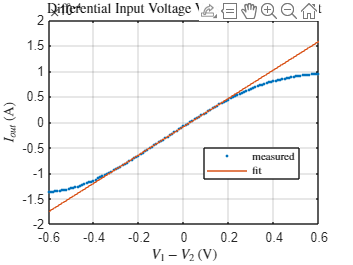


plot(Vdm, Iout,'.');
hold on;
plot(Vdm, Vdm*mmax + bmax);
grid on;
title("Differential Input Voltage Versus Output Current","Interpreter","latex")
xlabel("$V_{1}-V_{2}$ (V)","Interpreter","latex")
ylabel("$I_{out}$ (A)","Interpreter","latex")
legend("measured","fit","Interpreter","latex","Location","best")
hold off;